# ODE Fibroblast Encapsulation Model 

clear all; close all;

### Parameters

param.S=10; %implant size
param.R= 0.001; %debris removal rate
param.k0= 1; %M0 migration rate
param.Mmax= 10; %maximal M0
param.dM0= 0.1; %M0 apoptosis rate
param.vmax1= 0.1; %MM vmax rate M0 to M1
param.km1= 2; %MM km M0 to M1
param.dM1= 0.05; %M1 apoptosis rate
param.vmax2= 0.1; %MM vmax rate M0 to M2
param.km2= 1; %MM km M0 to M2
param.dM2= 0.01; %M2 apoptosis rate
param.kDc1= 0.01; %constant c1 production rate by debris
param.kM1= 0.1; %constant c1 production rate by M1
param.dc1= 0.5; %c1 removal rate
param.kM2= 0.1; %constant c2 production rate by M2
param.dc2= 0.5; %c2 removal rate 
param.kf= 0.01; %proliferation rate F
param.Fmax= 2; %maximal F
param.df= 0.2; %F apoptosis rate

#### Hill-type parameter estimation

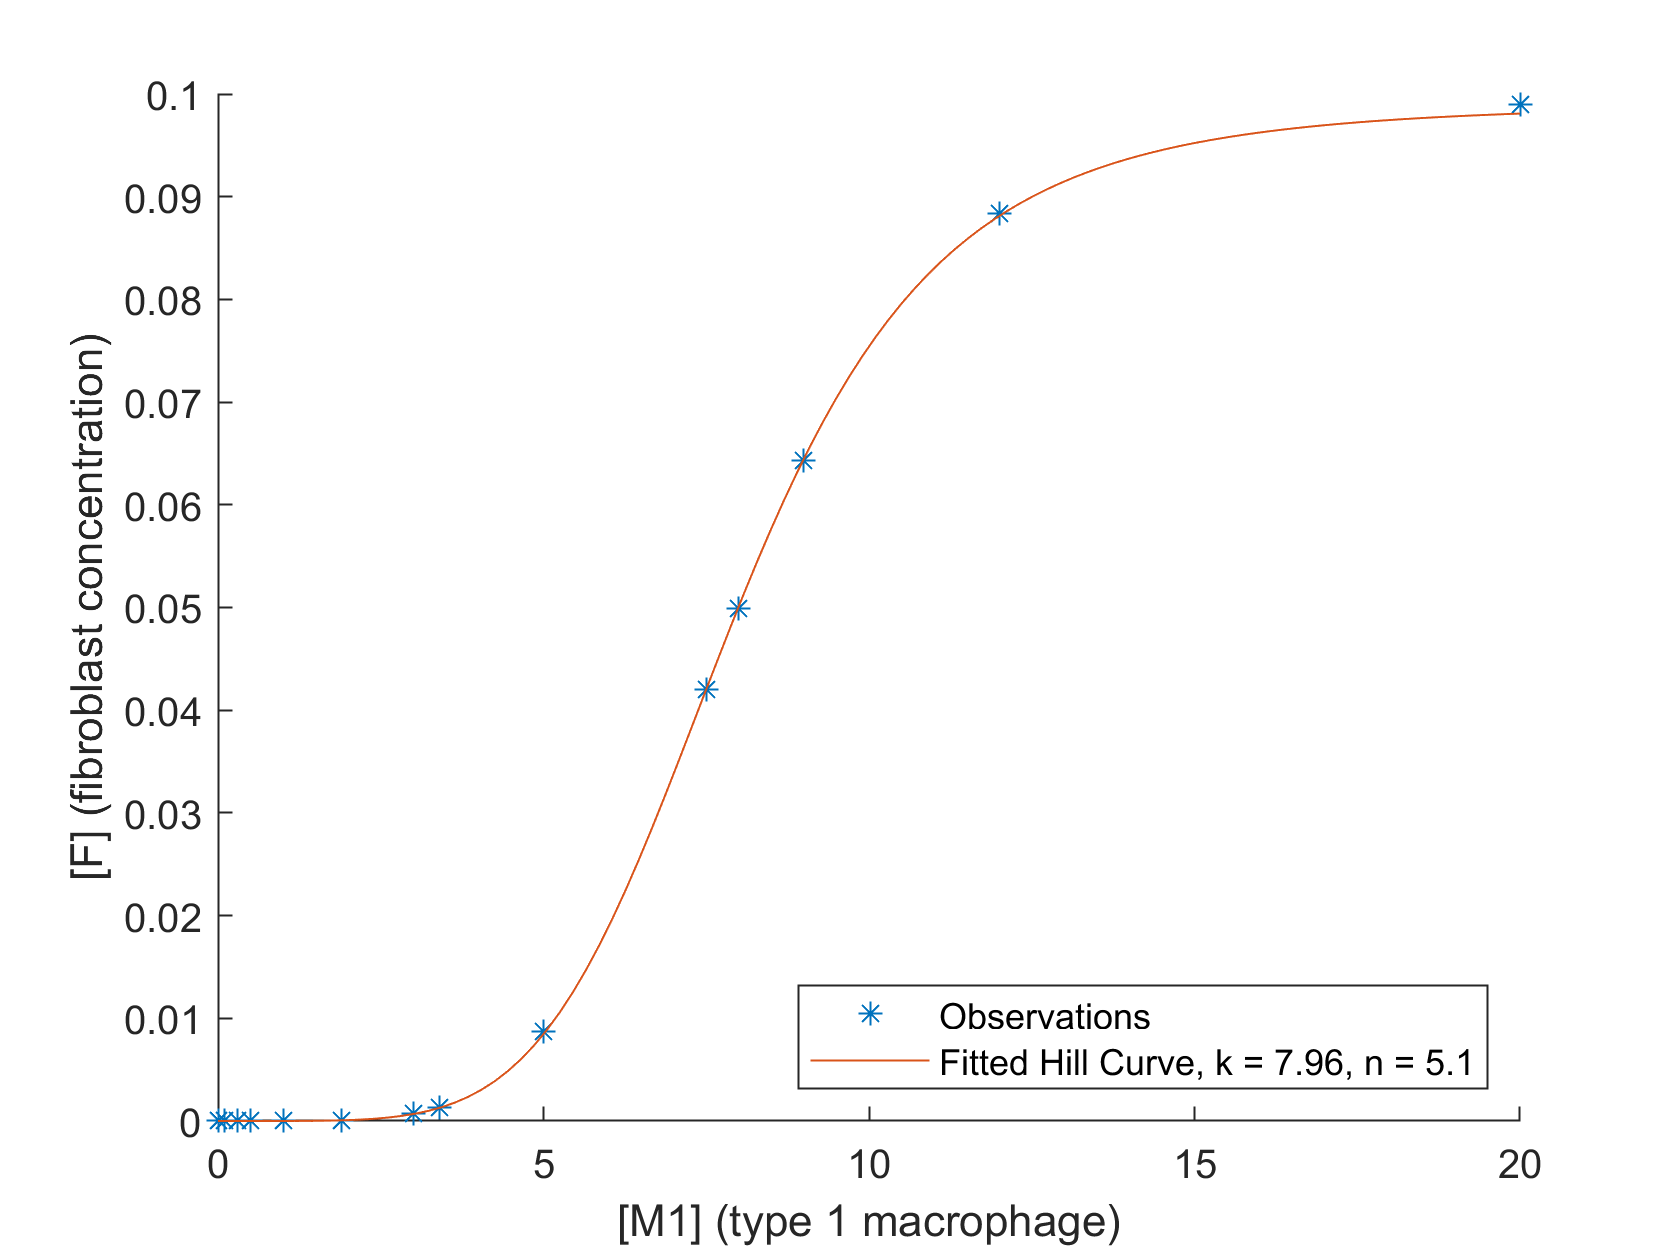

M1_obs = [0; 0.1; 0.3; 0.5;1; 1.9; 3; 3.4; 5; 7.5; 8; 9; 12; 20];
F_obs = [0; 3.04E-11; 7.45E-09; 9.54E-08; 3.01E-06; 7.55E-05; 0.000738; 0.001362; 0.008706; 0.042005; 0.0499; 0.064312; 0.088364; 0.098986];
param.FMM = max(F_obs); % maximum fibroblast migration rate
hn = 1:0.1:10;
hk = 0.1:0.01:max(M1_obs); 

for i = 1:length(hn)
    for j = 1 :length(hk)
        hill = hill_eq(hk(j),hn(i),M1_obs,param.FMM);
        RMSE(i, j) = sqrt(mean((F_obs - hill).^2));
    end
end


min_RMSE = min(RMSE,[],'all');
[x,y] = find(RMSE==min_RMSE);
param.hk = hk(y); %hill type parameter k (migration rate constant)
param.hn = hn(x); %hill type parameter n (power)

X = linspace(0,max(M1_obs));
hill_final = hill_eq(param.hk, param.hn,X,param.FMM);

figure;
hold on;
plot(M1_obs, F_obs,'*');
plot(X, hill_final);
xlabel('[M1] (type 1 macrophage)')
ylabel('[F] (fibroblast concentration)')
hname = ['Fitted Hill Curve, k = ', num2str(param.hk), ', n = ',num2str(param.hn)];
legend('Observations',hname,'Location','SouthEast')
hold off;

## Initial conditions (nondimensional)

% Set the time of the simulation
t0 = 0; tf = 10;  %(s)

% Set the initial condition
%         D; C1; C2; M0; M1; M2; F
x0_low = [10; 0.1; 0.1; 1; 0; 0; 0]; 
x0_high = [50; 0.1; 0.1; 1; 0; 0; 0]; 

%choose which amount of D to start with
x0 = x0_low;

% Solve the ODE system
[T,X] = ode15s(@fibroblastencaps,[t0 tf],x0,[],param);


% Plot the ODE solution
figure;
hold on
for i=1:length(x0)
    plot(T,X(:,i));
end  

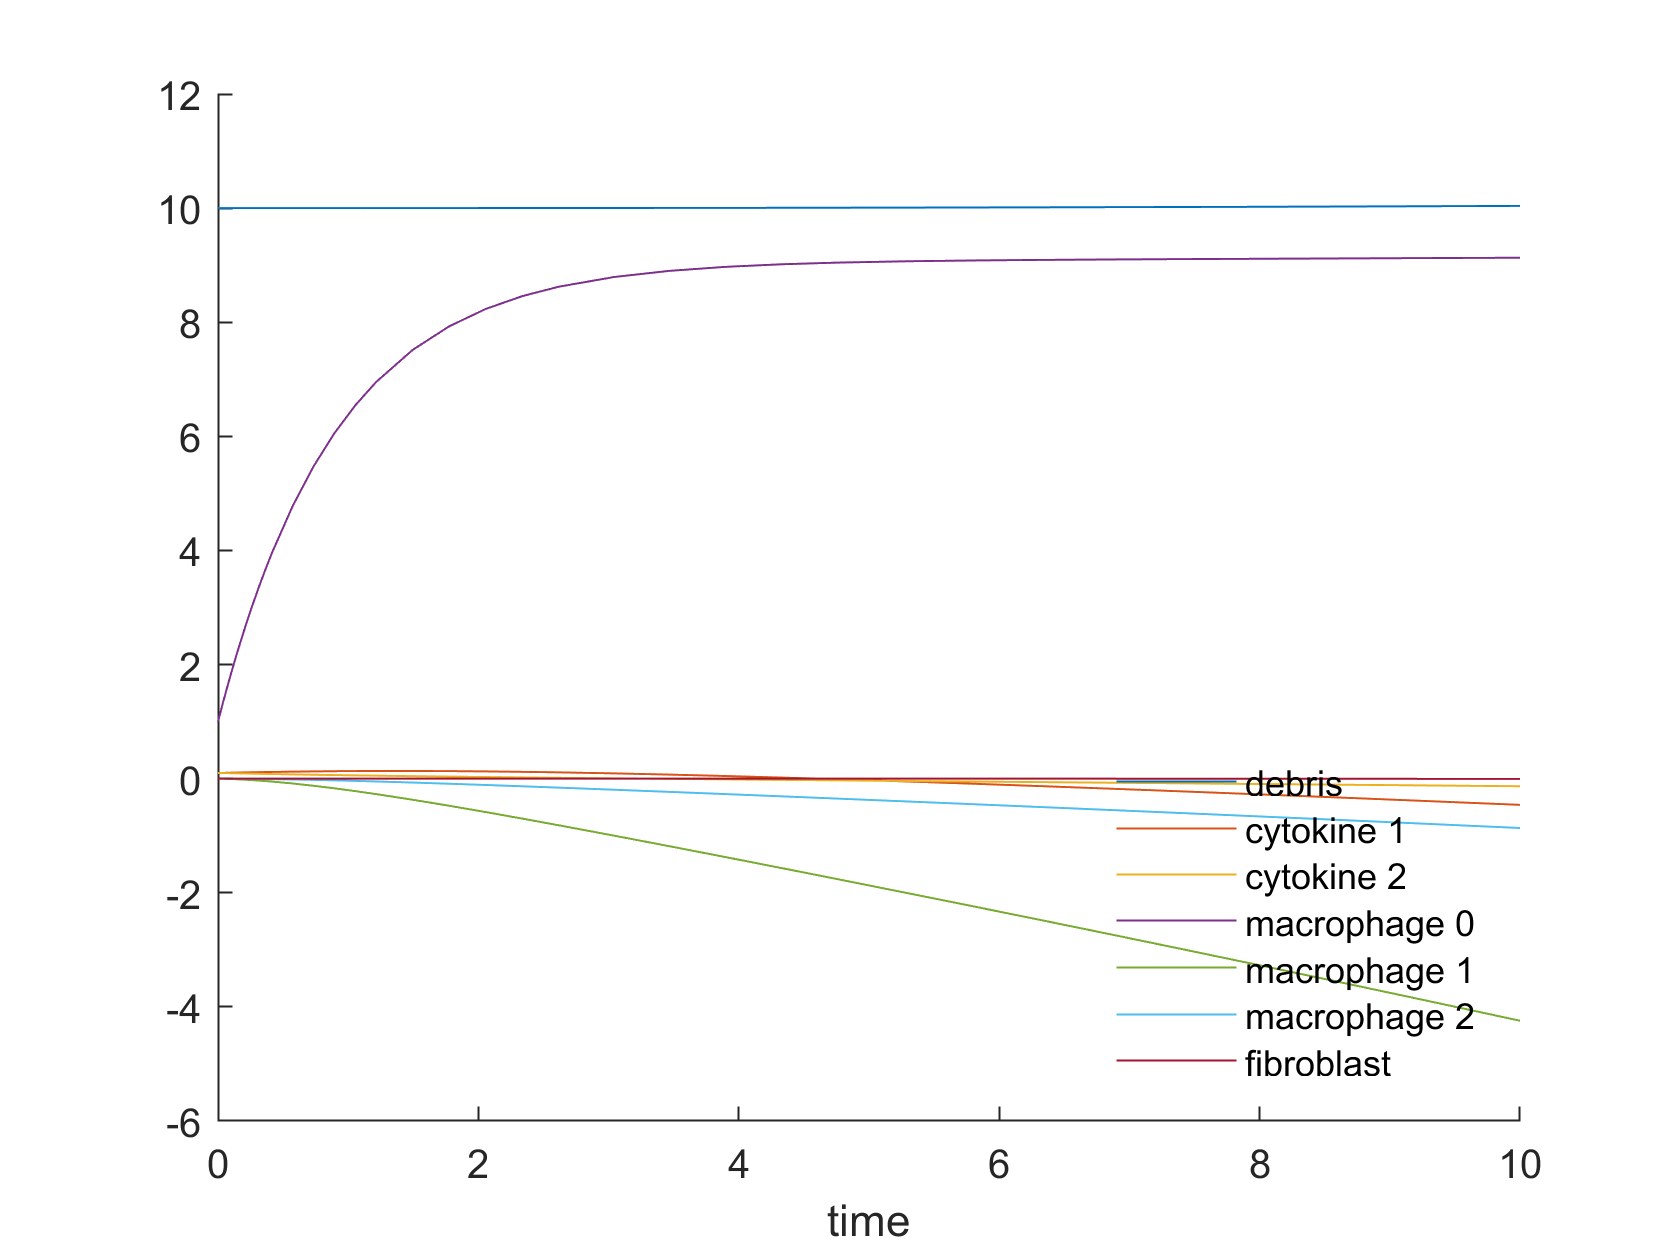

xlabel('time');
legend('debris', 'cytokine 1', 'cytokine 2','macrophage 0','macrophage 1','macrophage 2','fibroblast','Location','SouthEast');    legend('boxoff');

function dx=fibroblastencaps(t,x,param)
    D = x(1);
    C1 = x(2);
    C2 = x(3);
    M0 = x(4);
    M1 = x(5);
    M2 = x(6);
    F = x(7);
    
    dD = -param.R*M2*D;
    m1 = (param.vmax1*M0)/(param.km1 + M0); %michaelis-menten equation rate for transformation from M0 to M1
    m2 = (param.vmax2*M0)/(param.km2 + M0); %michaelis-menten equation rate for transformation from M0 to M2
    dM0 = D*param.k0*(1 -(M0/param.Mmax)) - C1*m1 - C2*m2 - param.dM0*M0; 
    dC1 = param.kDc1*D + param.kM1*M1 - param.dc1*C1;
    dC2 = param.kM2*M2 - param.dc2*C2;
    dM1 = C1*m1 - param.dM1*M0;
    dM2 = C2*m2 - param.dM2*M0;
    h = param.FMM*(M1^param.hn/(param.hk^param.hn + M1^param.hn));
    dF = param.kf*F*(1-F/param.Fmax) + h - param.df*F;
    
    dx = [dD; dC1; dC2; dM0; dM1; dM2; dF];
end


function c =hill_eq(k,n,C,MR) % hill type function
% INPUTS: 
    % k - rate constant
    % n - power 
    % C - independent concentration
    % MR - maximum rate
    c = MR*C.^n./(k^n + C.^n);
end